# Spatial transformations

## Modeling and Control of Robotic Manipulators

## Translations and rotations

#### 1. Translation along x- and z-axis

Define a 3-by-1 column vector *trvecx* for the translation $\mathbf{t}_x$ along the x-axis by $a=1$.

a=1;
trvecx=[a 0 0]'

trvecx =      1
     0
     0


Define a 3-by-1 column vector *trvecz* for the translation $\mathbf{t}_z$  along the z-axis by $d=2$ .

d=2;
trvecz=[0 0 d]'

trvecz =      0
     0
     2


#### 2. Rotations along x- and z-axis

Define a rotation matrix *rotmx* for the rotation$\;$$ $\mathbf{R}_x$$  around the x-axis by $$\alpha=\pi/2$$.

alpha=pi/2;
rotmx = [1 0 0; 0 cos(alpha) -sin(alpha); 0 sin(alpha) cos(alpha)];
% rotmx=axang2rotm([1 0 0 pi/4])

Define a rotation matrix *rotmz*  for the rotation $$\mathbf{R}_z$ $around the z-axis by $$\theta=\pi/4$$. 

theta=pi/4;
rotmz = [cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1]; 
% rotmz =axang2rotm([0 0 1 pi/4])

#### 3. Composition of rotations

 Compute the rotation *rotmc* resulting from sequential rotations first along the x-axis and then about the current z-axis (current frame, intrinsic).

rotmc=rotmx*rotmz  % intrinsic with respect to current frame

rotmc =     0.7071   -0.7071         0
    0.0000    0.0000   -1.0000
    0.7071    0.7071    0.0000


Compute the rotation *rotmf* resulting from sequential rotations along the x-axis and then along the fixed z-axis (fixed frame, extrinsic).

rotmf=rotmz*rotmx  % extrinsic with respect to fixed frame

rotmf =     0.7071   -0.0000    0.7071
    0.7071    0.0000   -0.7071
         0    1.0000    0.0000


#### 4. Apply rotations to 3D vector 

Apply the combined rotations *rotmc, rotmf*  to the 1-by-3 column vector *p *($\mathbf{p}=\left[ \begin{array}{ccc} 1 & 2  & 0 \end{array} \right] ^T$). 

p=[1 2 0]';
pc = rotmc*p

pc =    -0.7071
    0.0000
    2.1213


pf = rotmf*p

pf =     0.7071
    0.7071
    2.0000


#### 5. Apply rotations and translations to 3D vector

Apply the transformation


$$\mathbf{p}' = \mathbf{R}_x (\mathbf{R}_z (\mathbf{p}+\mathbf{t}_z) +\mathbf{t}_x)
$$


that corresponds to the consecutive application of the translation along z-axis by $d=2$, rotation along z-axis by $$\theta=\pi/4$$, translation along the x-axis by $$a=1$$ and final rotation along the x-axis by $$\alpha=\pi/2$$ to the 1-by-3 column vector *p*.

ptf = rotmx*(rotmz*(p+trvecz)+trvecx)

ptf =     0.2929
   -2.0000
    2.1213


## Homogeneous Transformations 

#### 6. Convert translations to homogeneous transforms

Define a transform *tformtx* for the homogeneous transformation $$\mathbf{H}_{tx}$$ that correspond to the previously defined translation* trvecx* along the x-axis by $$a=1$$.

tformtx=trvec2tform(trvecx')

tformtx =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


Define a transform *tformtz* for the homogeneous transformation $$\mathbf{H}_{tz}$ $that correspond to the previously defined translation trvecz along the z-axis by $$d=2$$.

tformtz=trvec2tform(trvecz')

tformtz =      1     0     0     0
     0     1     0     0
     0     0     1     2
     0     0     0     1


#### 7. Convert rotations to homogeneous transforms

Define a transform *tformrotx* for the homogeneous transformation $$\mathbf{H}_{Rx}$$ that corresponds to the previously defined rotation *rotmx* around the x-axis by $$\alpha=\pi/2$$.

tformrotx=rotm2tform(rotmx)

tformrotx =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


Define a homogeneous transform *tformrotz* for the homogeneous transformation $$\mathbf{H}_{Rz}$ $ that correspond to the previously defined rotation *rotmz* around the z-axis by $$\theta=\pi/4$$.

tformrotz=rotm2tform(rotmz)

tformrotz =     0.7071   -0.7071         0         0
    0.7071    0.7071         0         0
         0         0    1.0000         0
         0         0         0    1.0000


#### 8. Composition of homogeneous transforms w.r.t. current frame

Generate a homogeneous transformation *tformdhc* that corresponds to the consecutive application of the translation along z-axis by $$d=2$$, rotation along z-axis by $$\theta=\pi/4$ $, translation along the new x-axis by $$a=1$$ and final rotation along the new x-axis by $$\alpha=\pi/2$$. Generate *tformdhc* by post-multiplying the transforms *tformtz*, *tformrotz*,  *tformtx* and *tformrotx*.


$$\mathbf{H}_{dhc}  =  \mathbf{H}_{tz}  \mathbf{H}_{Rz}  \mathbf{H}_{tx}   \mathbf{H}_{Rx}$$
 

which corresponds to transformations w.r.t. current frame.

tformdhc=tformtz*tformrotz*tformtx*tformrotx

tformdhc =     0.7071   -0.0000    0.7071    0.7071
    0.7071    0.0000   -0.7071    0.7071
         0    1.0000    0.0000    2.0000
         0         0         0    1.0000


Notice, that this composition of elemental translations and rotations provides the basis for the Denavit- Hartenberg representation of robot arm forward kinematics that are covered in the next lab.

#### 9. Composition of homogeneous transforms w.r.t. fixed frame

Generate a homogeneous transformation *tformdhc* that corresponds to the consecutive application of the translation along z-axis by $$d=2$$, rotation along z-axis by $$\theta=\pi/4$ $, translation along the new x-axis by $$a=1$$ and final rotation along the new x-axis by $$\alpha=\pi/2$$. Generate *tformdhc* by post-multiplying the transforms *tformtz*, *tformrotz*,  *tformtx* and *tformrotx*.


$$\mathbf{H}_{dhf} =\mathbf{H}_{Rx}  \mathbf{H}_{tx}  \mathbf{H}_{Rz}   \mathbf{H}_{tz}$$
 

which corresponds to transformations w.r.t. fixed frames.

tformdhf=tformrotx*tformtx*tformrotz*tformtz

tformdhf =     0.7071   -0.7071         0    1.0000
    0.0000    0.0000   -1.0000   -2.0000
    0.7071    0.7071    0.0000    0.0000
         0         0         0    1.0000


#### 10. Apply homogeneous transform to homogeneous 4D vector

Apply the homogeneous transform *tformdhf* to the homogeneous 1-by-4 column vector *P* ($\mathbf{P}=\left[ \begin{array}{ccc} 1 & 2  & 0 & 1\end{array} \right] ^T$)


$${\mathbf{P}}^{\prime } ={\mathbf{H}}_{\textrm{dh}} \mathbf{P}$$


P=[p; 1];
Ptf=tformdhf*P

Ptf =     0.2929
   -2.0000
    2.1213
    1.0000


#### 11. Compare 3D vector and 4D vector for equality

Compare the corresponding resulting homogeneous 4D vector $\mathbf{P}'$  with the 3D vector $\mathbf{p}'$ previously  generated by the application of the same sequence of transformations in assignment 5. The 3D projection of $\mathbf{P}'$ is supposed to equal $\mathbf{p}'$.

if isequal(Ptf(1:3),ptf)
    display('ptf and Ptf are equal');
else
    display('ptf and Ptf are not equal');
end

ptf and Ptf are equal


## Rigid Body Tree Robot Model

#### 12. Create a rigid body tree

Create a rigid body tree *rbtree* with the method `robotics.RigidBodyTree`.

rbtree = robotics.RigidBodyTree;

#### 13. Create a rigid body object

Create a rigid body object *body1* with the name *'b1'* with the method `robotics.RigidBody`*.*

body1 = robotics.RigidBody('b1');

#### 14. Create a joint object

Create a joint object *joint1* of joint type 'fixed' with the name *'tz'* with the method `robotics.Joint`. Assign  the translation along the z-axis *tformtz* to the transform of joint *joint1* with the method `setFixedTransform`. Assign *joint1* to the joint property *body1.Joint* of the rigid body object *body1*.

joint1=robotics.Joint('tz','fixed');
setFixedTransform(joint1,tformtz)
body1.Joint=joint1;
% short form:
% body1.Joint.setFixedTransform(tformtz);

#### 15. Add rigid body object to rigid body tree

Add the rigid body object *body1* to the rigid body tree *rbtree* by attaching it to the baseframe 'base' as its parent body with `addbody`.

basename = rbtree.BaseName;
rbtree.addBody(body1,'base');

#### 16. Display the kinematic structure of the rigid body tree

Display the kinematic structure of the rigid body tree *rbtree* with `showdetails`.

rbtree.showdetails();

--------------------
Robot: (1 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1           b1           tz        fixed             base(0)   
--------------------


#### 17. Visualize the rigid body tree

Visualize the base frame and the first rigid body frame of *rbtree* with `show`.

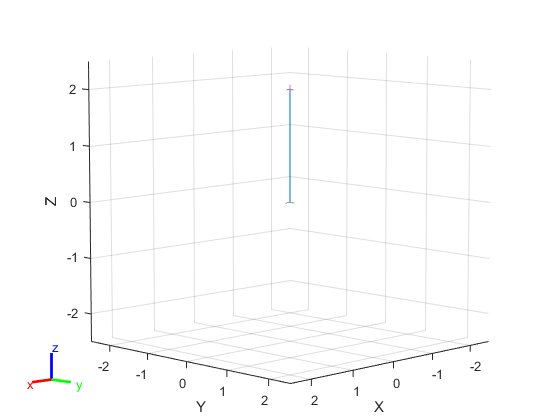

rbtree.show();

#### 18. Configure and attach consecutive bodies 

Proceed in the same way to generate, configure and attach consecutive bodies *body2,body3,body4* with names *'b2','b3','b4' *with corresponding joints with fixed transforms *tformrotz, tformtx* and *tformrotx*. Connect the bodies in series such that body $b_{i-1}$ becomes the parent for body $b_i$.

body2 = robotics.RigidBody('b2');
joint2=robotics.Joint('Rz','fixed');
setFixedTransform(joint2,tformrotz)
body2.Joint=joint2;

body3 = robotics.RigidBody('b3');
joint3=robotics.Joint('tx','fixed');
setFixedTransform(joint3,tformtx);
body3.Joint=joint3;

body4 = robotics.RigidBody('b4');
joint4=robotics.Joint('Rx','fixed');
setFixedTransform(joint4,tformrotx)
body4.Joint=joint4;
rbtree.addBody(body2,'b1');
rbtree.addBody(body3,'b2');
rbtree.addBody(body4,'b3');

#### 19. Display and visualize

Display and visualize the overall kinematic structure of the rigid body tree. The rigid body tree should resemble figure 7.

rbtree.showdetails()

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1           b1           tz        fixed             base(0)   b2(2)  
   2           b2           Rz        fixed               b1(1)   b3(3)  
   3           b3           tx        fixed               b2(2)   b4(4)  
   4           b4           Rx        fixed               b3(3)   
--------------------


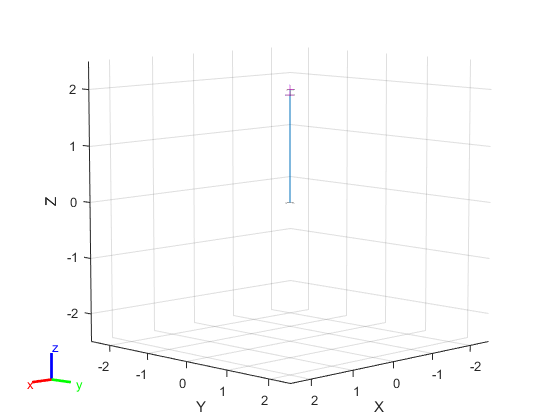

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


rbtree.show()

% axis([-0.25,1.3,-0.25,1.3,-0.25,1.3])

#### 20. Retrieve the transformation between two body frames 

Use `robotics.RigidBodyTree.getTransform` to retrieve the transformation between two body frames. Retrieve the transformation from the fourth body frame *'b4'* to the base *'base'*.

config = rbtree.homeConfiguration;
tformdhrbtree = rbtree.getTransform(config,'b4','base')

tformdhrbtree =     0.7071   -0.0000    0.7071    0.7071
    0.7071    0.0000   -0.7071    0.7071
         0    1.0000    0.0000    2.0000
         0         0         0    1.0000


In our case the `config` is an empty structure array as our rigid body tree is only composed of fixed joints and possesses no articulated joints .

#### 21. Compare manually define DH transform with rigid body tree transform

Check whether the transform *tformdhrbtree* retrieved from the rigid body tree is identical with the previously manually defined transform *tformdhc* w.r.t. current frame in in assignment 8.

if isequal(tformdhc,tformdhrbtree)
    display('tformdhc and tformdhrbtree are equal');
else
    display('tformdhc and tformdhrbtree are not equal');
end

tformdhc and tformdhrbtree are equal


#### 22. Load point cloud and visualization

The code 

edgelength=0.2;
c=0:edgelength/20:edgelength;
p=edgelength*ones(1,length(c));
%Create point cloud data of a cuboid of side length 0.2 0.16 0.12 at the origin.
p=[[0*p; 0*p; c*0.6],[p; 0*p; c*0.6],[p; p*0.8; c*0.6],[0*p; p*0.8; c*0.6],...
   [0*p; c*0.8; 0*p],[p; c*0.8; p*0.6],[0*p; c*0.8; p*0.6],[p; c*0.8; p*0],...
   [c; 0*p; 0*p],[c; p*0.8; 0*p],[c; 0*p; p*0.6],[c; p*0.8; p*0.6]]; 

generates a point cloud p that represents the edges of a cuboid with side lengths a = 0.2, b = 0.16, c = 0.12. Either use the above code or load (load) the point cloud from the MAT-file with

%load 'pointcloud.mat'; % or load data

Superimpose the point cloud on your rigid body tree visualization by plotting the points with `plot3` w.r.t. base frame. 

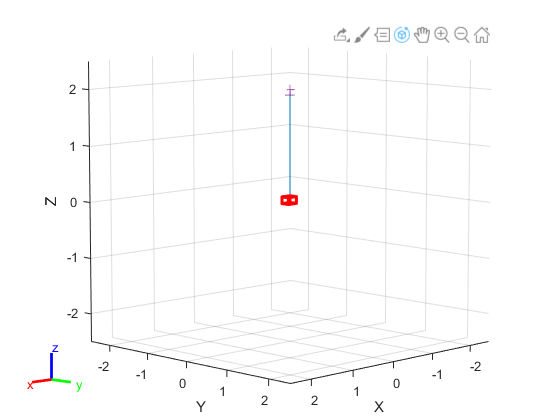

hold on;
% plot point cloud w.r.t. to base frame, Overlay point cloude with rigid body
plot3(p(1,:),p(2,:),p(3,:),'r.');

#### 23. Transform the point cloud into a frame

Transform the point cloud into the frame 'b4'. For that purpose apply the homogeneous transform *tformdhrbtree* to the point cloud* p* (convert the 3-by-n matrix *p* into a 4-by-n matrix of homogeneous 4-by-1 column vectors). 

tp=tformdhrbtree*[p; ones(1,length(p))]; %apply transform to homogeneous 4D vector of point cloud data

Visualize the transformed point cloud which is supposed to depict the same cuboid w.r.t. to frame 'b4' as shown in figure 8.

plot3(tp(1,:),tp(2,:),tp(3,:),'b.'); %plot point cloud w.r.t. to b4 frame

## Conversion to Euler Angles, Roll Pitch Yaw and Angle Axis

#### 24. Euler angles, roll-pitch-yaw and angle-axis representation

Extract the Euler angles, roll-pitch-yaw and angle-axis representation of the rotation associated with the transform `tformdhrbtree` from assignment 20.

eul=tform2eul(tformdhrbtree,'ZYZ')

eul =     2.3562   -1.5708   -1.5708


rpy=tform2eul(tformdhrbtree,'ZYX')

rpy =     0.7854         0    1.5708


axanga=tform2axang(tformdhrbtree)

axanga =     0.8629    0.3574    0.3574    1.7178


## Representation Singularities

The task starts with the roll, pitch and yaw angles $$\alpha=\pi/4, \beta=\pi/2, \gamma=\pi/4$ 
$.

#### 25. Compose a rotation matrix

From the roll, pitch and yaw angles $$\alpha, \beta, \gamma$ $ compose a rotation matrix *rotmrpy* **R** with `eul2rotm` . 

rotmrpy = eul2rotm([pi/4, pi/2, pi/4],'ZYX')

rotmrpy =     0.0000         0    1.0000
    0.0000    1.0000         0
   -1.0000    0.0000    0.0000


#### 26. Transform rotation matrix back into roll, pitch and yaw angles

Transform the rotation matrix **R** back into roll, pitch and yaw angles. Compare the result with the original angles $$\alpha=\pi/4, \beta=\pi/2$$ and $$\gamma=\pi/4$$. 

alphabetagamma = rotm2eul(rotmrpy,'ZYX')

alphabetagamma =          0    1.5708         0


## Quaternion Slerps

Euler angle interpolation (not part of the assignment but for the sake of comparison)

path = 0:0.05:1;
p = [1,0,0];
interpolatedEuler=eul2rotm([pi/3, -pi/2, 0]...
+[-path*2*pi/3;path*pi*1.05;path*0]','ZYX');
for i=1:21
  rPeul(i,:)=interpolatedEuler(:,:,i)*p';
end
plot3(rPeul(:,1),rPeul(:,2),rPeul(:,3),'r-d');
hold on; 
quiver3(zeros(21,1),zeros(21,1),zeros(21,1),...
rPeul(:,1),rPeul(:,2),rPeul(:,3),'r')

#### 27. RPY-angles (ZYX Euler) to quaternion

Calculate the quaternion *q0* and *q1* that correspond to the initial $ $[\psi, \vartheta, \varphi]_{i}=[\pi/3,\ -\pi/2, \ 0]$
$ and final ZYX-Euler angles (RPY-angles)  $$[\psi, \vartheta, \varphi]_f=[-\pi/3, \ \pi/2+ \pi/20, \ 0]$
$ with

q0 = quaternion([pi/3,-pi/2,0],'euler','ZYX','frame');
q1 = quaternion([-pi/3,pi/2+0.02,0],'euler','ZYX','frame');

#### 28. SLERP interpolation

Calculate the quaternion array *interpolatedQuaternions* from the quaternion slerp between the initial quaternion *q0* and the final quaternion *q1* with increments of 0.05.

path = 0:0.05:1;
interpolatedQuaternions = slerp(q0,q1,path);

#### 29. Apply the array of interpolated quaternions to a vector

 Apply the array of interpolated quaternions to the vector **p**=[1, 0, 0] with:

p = [1,0,0];
rP = rotatepoint(interpolatedQuaternions,p);

#### 30. Visualize rotations of the vector by the quaternion slerp

Visualize rotations of the vector **p**=[1, 0, 0]  by the quaternion slerp and compare the trajectory with the Euler angle interpolation in figure 14.

clf;
plot3(rP(:,1),rP(:,2),rP(:,3),'b-d');
axis([-1 1 -1 1 -1 1]);
grid on;
hold on;
quiver3(zeros(21,1),zeros(21,1),zeros(21,1),rP(:,1),rP(:,2),rP(:,3),'b')
xlabel('x');
ylabel('y');
zlabel('z');

#### 31. Rotate by pi/2 to obtain opposite great circle arc

Modify the final rotation to $$[\psi, \vartheta, \varphi]_f=[-\pi/3, \ \pi/2, \ 0]$
$. What is the effect on the great circle arc obtained by SLERP?

q2 = quaternion([-pi/3,pi/2,0],'euler','ZYX','frame');
interpolatedQuaternions = slerp(q0,q2,path);
rP = rotatepoint(interpolatedQuaternions,p);
plot3(rP(:,1),rP(:,2),rP(:,3),'r-d');
quiver3(zeros(21,1),zeros(21,1),zeros(21,1),rP(:,1),rP(:,2),rP(:,3),'r');